## Tutorial 2 – Conceitos Básicos de Sistemas Lineares

1. Suponha que a resposta de um sistema dinâmico seja dado por: x(t) = −10e^( −t) + cos(5t), t ≥ 0

- Achar a resposta transitória e a resposta permanente. 

- Plotar a resposta transitória, a resposta permanente e a resposta do sistema em uma mesma figura usando Matlab.

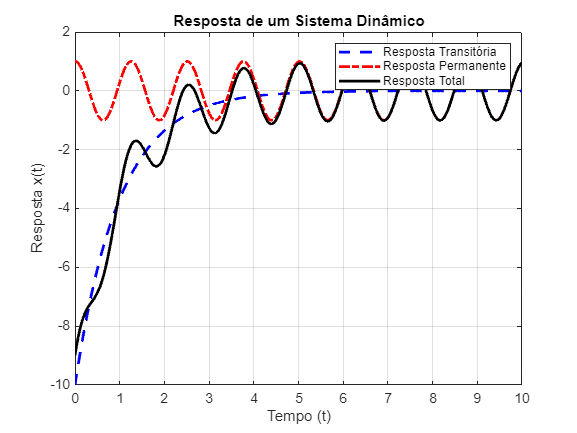

t = linspace(0, 10, 1000); 

x_trans = -10*exp(-t);


x_perm = cos(5*t);

x_total = x_trans + x_perm;

figure; 
plot(t, x_trans, 'b--', 'LineWidth', 2); 
hold on; 
plot(t, x_perm, 'r-.', 'LineWidth', 2); 
plot(t, x_total, 'k', 'LineWidth', 2); 

legend('Resposta Transitória', 'Resposta Permanente', 'Resposta Total');
title('Resposta de um Sistema Dinâmico');
xlabel('Tempo (t)');
ylabel('Resposta x(t)');

grid on; 

2. O modelo matemático de sistemas mecânicos com 1GDL com apenas uma massa m, uma mola k e um amortecedor c é dado pela EDOL 

mx¨ + cx˙ + kx = f(t) 

sendo x(t) a resposta no tempo e f(t) a excitação. 

- Calcular a função de transferência do sistema. 

- Mostrá-la de forma simbólica usando Matlab. Nota: usar o comando pretty. 

- Aplicar uma excitação do tipo degrau unitário e apresentar a resposta x(t) de forma gráfica. Assumir os seguintes parâmetros do sistema: m = 1kg, c = 2N.s/m e k = 4N/m. 

m = 1; 
c = 2; 
k = 4; 

% função de transferência H(s) = X(s)/Y(s)
num = 1; 
den = [m c k]; 

H = tf(num, den)

H =
 
        1
  -------------
  s^2 + 2 s + 4
 
Continuous-time transfer function.
Model Properties


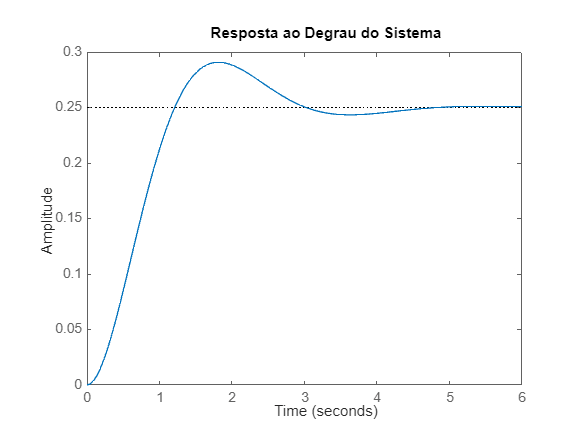

figure;
step(H);
title('Resposta ao Degrau do Sistema');

Nota: Simular usando o comando step do Matlab. 

3. O modelo matemático do sistema mecânico da Figura 18 á dado por 

mx¨ + cx˙ + kx = cy˙ + ky

sendo x(t) o deslocamento da massa ao longo do tempo e y(t) é a excitação do tipo deslocamento da base. 

- Calcular a função de transferência do sistema.

- Mostrá-la de forma simbólica usando Matlab.

m = 1; 
c = 2; 
k = 4; 

% função de transferência H(s) = F(s)/X(s)
num2 = [c k]; 
den2 = [m c k]; 

H2 = tf(num2, den2)

H2 =
 
     2 s + 4
  -------------
  s^2 + 2 s + 4
 
Continuous-time transfer function.
Model Properties


- Aplicar ao sistema uma excitação senoidal com amplitude 2 e frequência 1rad/s.

- Apresentar a resposta x(t) de forma gráfica. Assumir os seguintes parâmetros do sistema: m = 1kg, c = 2N.s/m e k = 4N/m.

- Calcular a resposta temporal x(t) para a entrada do item anterior.

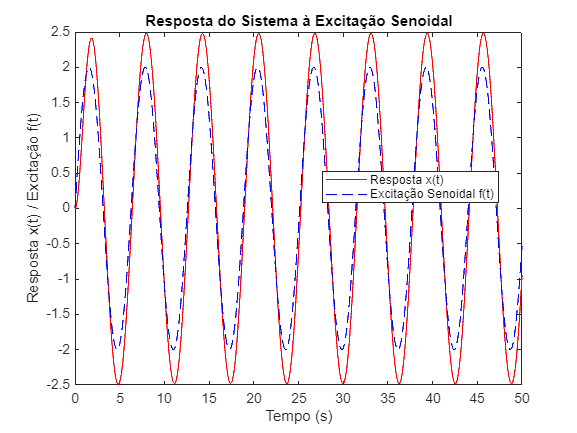

t = 0:0.01:50; 
f = 2 * sin(1 * t);

[y, t] = lsim(H2, f, t);

figure; 
plot(t, y, 'r-'); 
hold on;
plot(t, f, 'b--'); 
hold off;
title('Resposta do Sistema à Excitação Senoidal');
xlabel('Tempo (s)');
ylabel('Resposta x(t) / Excitação f(t)');
legend('Resposta x(t)', 'Excitação Senoidal f(t)', 'Location', 'Best');

4. Calcular a Transformada de Laplace do sinal mostrado na Figura 19.

Sugestão: Usar a definição de Transformada de Laplace e usar integração por partes.

syms t s 

r(t) = 2*t;
lp = laplace(r, t, s)

$$lp = \frac{2}{s^{2}}$$

5. Calcular a Transformada de Laplace do pulso triangular da Figura 20 e simulá-lo usando Matlab.

clear
syms t s

tri1(t) = 2*t*heaviside(t) - 2*t*heaviside(t-1); 
tri2(t) = 2*(2-t)*heaviside(t-1) - 2*(2-t)*heaviside(t-2);

f(t) = tri1(t) + tri2(t);

% Laplace
L_tri1 = laplace(tri1, t, s);
L_tri2 = laplace(tri2, t, s);
L_tri = L_tri1 + L_tri2

$$L\_tri = \frac{2\,{\mathrm{e}}^{-2\,s}}{s^{2}}-\frac{2\,{\mathrm{e}}^{-s}}{s^{2}}-\frac{2\,{\mathrm{e}}^{-s}}{s}+\frac{2}{s^{2}}+\frac{2\,{\mathrm{e}}^{-s}\,\left(s-1\right)}{s^{2}}$$

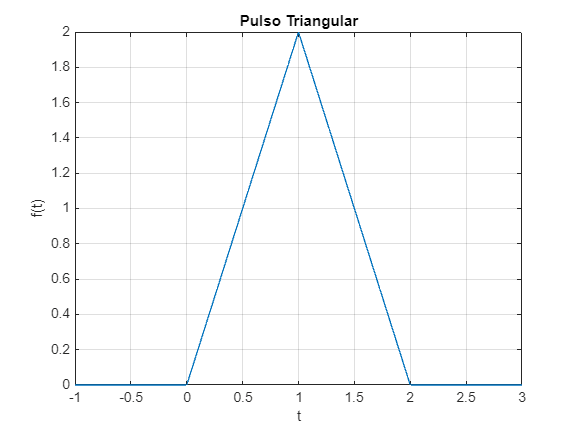


% Simulacao
fplot(f, [-1, 3]); 
xlabel('t');
ylabel('f(t)');
title('Pulso Triangular');
grid on;

6. Dada a Figura 21, encontrar a Transformada de Laplace da função e reproduzi-la em MatLab.

syms s

lpy = -2/s^3 + 1/s^2

$$lpy = \frac{1}{s^{2}}-\frac{2}{s^{3}}$$

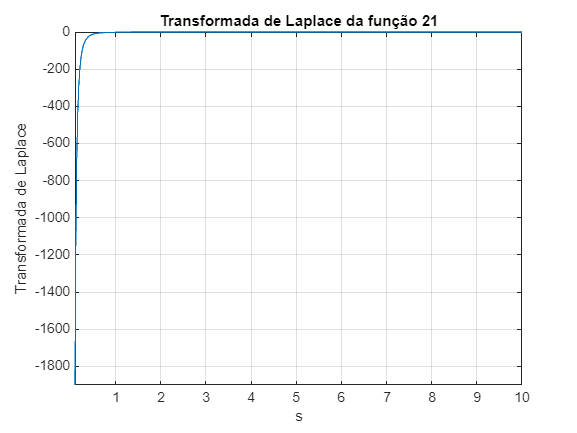


sRange = [0.1, 10];

fplot(lpy, sRange)

xlabel('s')
ylabel('Transformada de Laplace')
title('Transformada de Laplace da função 21')
grid on

7. Na Figura 22 são apresentados alguns forçamentos que podem ser obtidos a partir de combinações de outros forçamentos.

Com base na Figura 22, gerar o pulso trapezoidal conforme ilustrado na Figura 23 utilizando o MatLab, onde F0 = 10N , t1 = 1s, t2 = 2s, t3 = 2s.

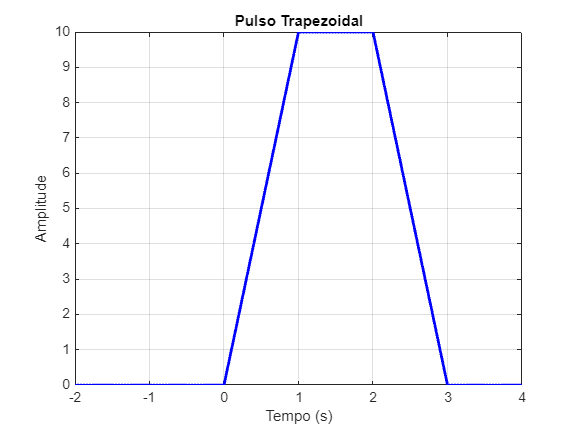

subida = 1;   
constante = 1;      
altura = 10;     
descida = 1;

t = -2:0.01:4;  

pulse = zeros(size(t));
pulse(t >= 0 & t < subida) = altura * t(t >= 0 & t < subida) / subida;
pulse(t >= subida & t < subida + constante) = altura;
pulse(t >= subida + constante & t < subida + constante + descida) = altura * (1 - (t(t >= subida + constante & t < subida + constante + descida) - subida - constante) / descida);

plot(t, pulse, 'b', 'LineWidth', 2)
xlabel('Tempo (s)')
ylabel('Amplitude')
title('Pulso Trapezoidal')
grid on